clear all;
close all;
clc;

**Load the Pod Pull Model**

Iz1 = 0.312139172173821655e-5;
Iz3 = 0.368822e-2;
L1  = 0.119246383073931816e-1;
LF  = 0.124e0;
LFb = 0.58e-1;
LP  = 0.149999999999999994e0;
anc = 0.500000000000000028e-1;
g   = 0.981e1;
m1  = 0.359209895702164855e-1;
m3  = 0.2876e1;
psi = pi / 0.12e2;
x1  = -0.285618921376901667e-2;
x4  = 0.2095e0; 
y1  = 0.207405752586204278e0;
y4  = 0.209e0;
s__closed = 0.134279251077105213e-1;

ode = DRS_DAE3(g,m1,m3,psi,anc,LFb,LP,Iz3);

**Initialize 3 solvers for comparison**

solver_EE = LobattoIIIA();
solver_IE = ImplicitEuler();
solver_HH = Heun();

solver_EE.setODE(ode);
solver_IE.setODE(ode);
solver_HH.setODE(ode);

**Set time-step and initial conditions for solvers**

Tmax = 0.050;
hh    = 0.0001;
tt   = 0:hh:Tmax;


## Set up initial conditions

s0          = 0.0135632255529807288;
theta10     = -0.1934973650;
theta30     = 3.796091123;
s__dot0     = 0;
theta3_dot0 = 0;
lambda10    = 1879.889060;
lambda20    = -368.3624101;


ini = [s0,theta10,theta30,s__dot0,theta3_dot0,lambda10,lambda20];


**Compute the solutions**

sol_EE = solver_EE.advance(tt,ini,false,true,1e6);

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNe

sol_IE = solver_IE.advance(tt,ini,true,true,1e6);

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
 70%
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNewton do not converge ierr = 2
NewtonSolver: alpha = 8.88178e-16 Failed linesearch!
solveStepByNe

sol_HH = solver_HH.advance(tt,ini,true,true,1e5);

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


**Extract computed solution**

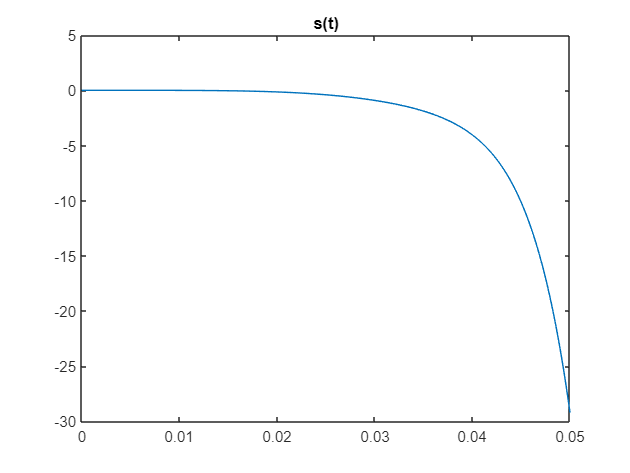

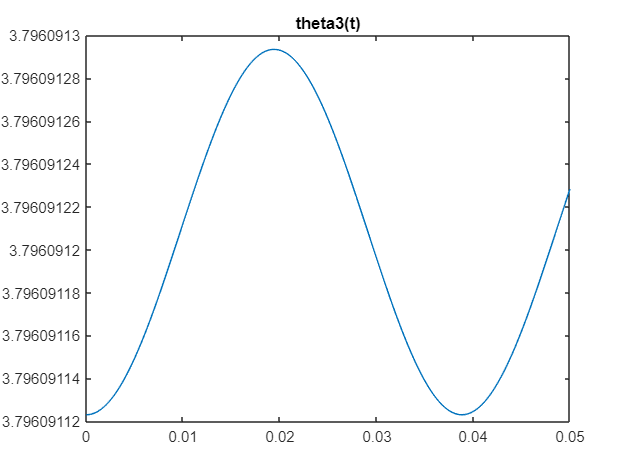

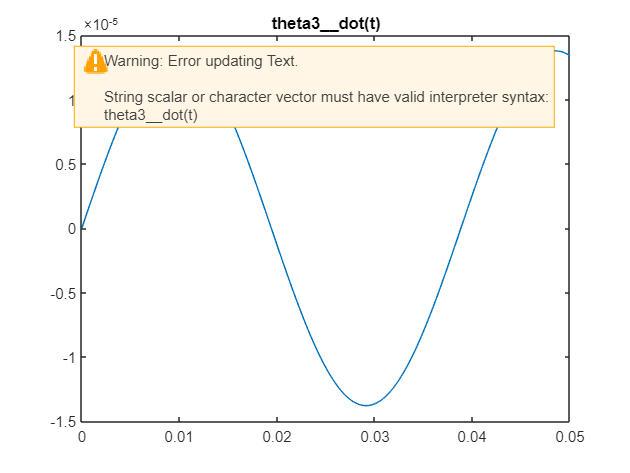

ode.plot(tt,sol_HH)